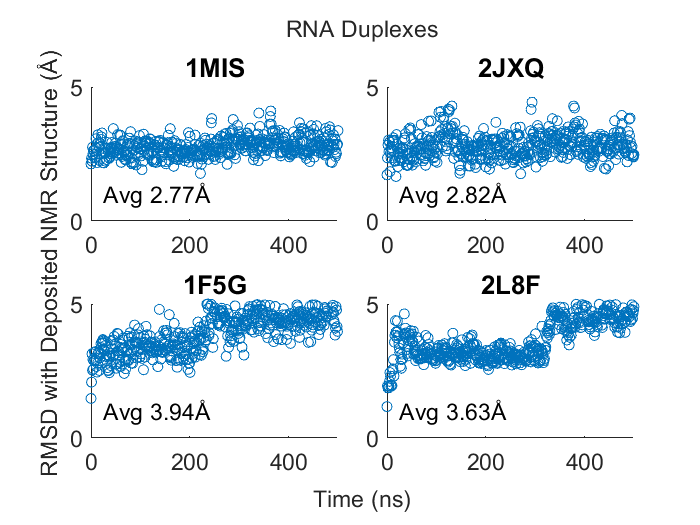

% Nucleic Acids
% Read in trajectory RMSD and sampled trajectory RMSD files for RNA/DNA
fullNucTable = readtable("files/nucleicTrajectoryRMSDs.csv");
sampledNucTable = readtable("files/sampled_nucleicTrajectoryRMSDs.csv");
variables = fullNucTable.Properties.VariableNames;
Ang=char(197);

% Plot Heavy Atom (ha) RMSDs
t1 = tiledlayout(2,2);
% RNA Helices
nexttile
plotRna(sampledNucTable.x1mis_ntha,fullNucTable.x1mis_ntha, '1MIS')
nexttile
plotRna(sampledNucTable.x2jxq_ntha, fullNucTable.x2jxq_ntha, '2JXQ')
nexttile
plotRna(sampledNucTable.x1f5g_ntha, fullNucTable.x1f5g_ntha, '1F5G')
nexttile
plotRna(sampledNucTable.x2l8f_ntha, fullNucTable.x2l8f_ntha, '2L8F')
title(t1,"RNA Duplexes",'FontSize',14)
xlabel(t1,"Time (ns)",'FontSize',14)
ylabel(t1,['RMSD with Deposited NMR Structure ', '(' Ang ')'],'FontSize',14)
t1.TileSpacing='compact';

% RNA Hairpins
t2=tiledlayout(2,2);

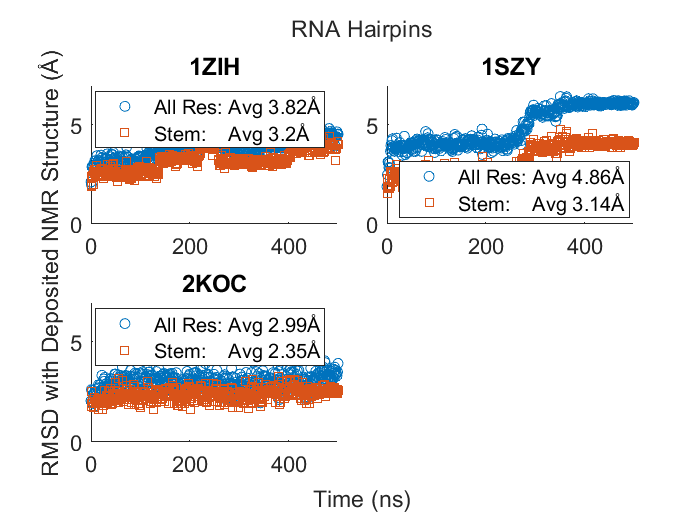

nexttile
plotHairpin(sampledNucTable.x1zih_ntha,sampledNucTable.x1zihstem_ntha,fullNucTable.x1zih_ntha,fullNucTable.x1zihstem_ntha,'1ZIH')
nexttile
plotHairpin(sampledNucTable.x1szy_ntha,sampledNucTable.x1szystem_ntha,fullNucTable.x1szy_ntha,fullNucTable.x1szystem_ntha,'1SZY')
nexttile
plotHairpin(sampledNucTable.x2koc_ntha,sampledNucTable.x2kocstem_ntha,fullNucTable.x2koc_ntha,fullNucTable.x2kocstem_ntha,'2KOC')
title(t2,"RNA Hairpins",'FontSize',14)
xlabel(t2,"Time (ns)",'FontSize',14)
ylabel(t2,['RMSD with Deposited NMR Structure ', '(' Ang ')'],'FontSize',14)
t2.TileSpacing='compact';

% DNA
t3 = tiledlayout(1,2);

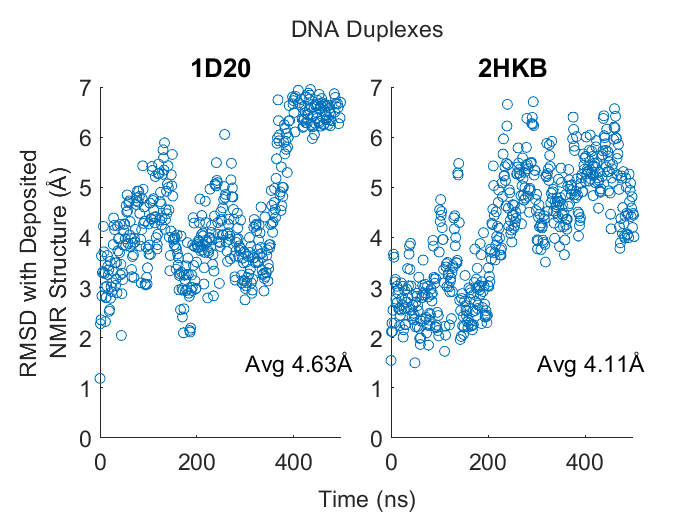

nexttile
plotDna(sampledNucTable.x1d20_ntha, fullNucTable.x1d20_ntha, '1D20')
nexttile
plotDna(sampledNucTable.x2hkb_ntha, fullNucTable.x2hkb_ntha, '2HKB')
title(t3,"DNA Duplexes",'FontSize',14)
xlabel(t3,"Time (ns)",'FontSize',14)
ylabel(t3,["RMSD with Deposited","NMR Structure ("+Ang+")"],'FontSize',14)
t3.TileSpacing='compact';

% Proteins
% Read in trajectory RMSD and sampled trajectory RMSD files for proteins
fullProteinTable=readtable("files/proteinTrajectoryRMSD_byTimestep.csv");
sampledProteinTable=readtable("files/sampled_proteinTrajectoryRMSD_byTimestep.csv");
% Plot backbone (bb) RMSDs
t4=tiledlayout(3,3);

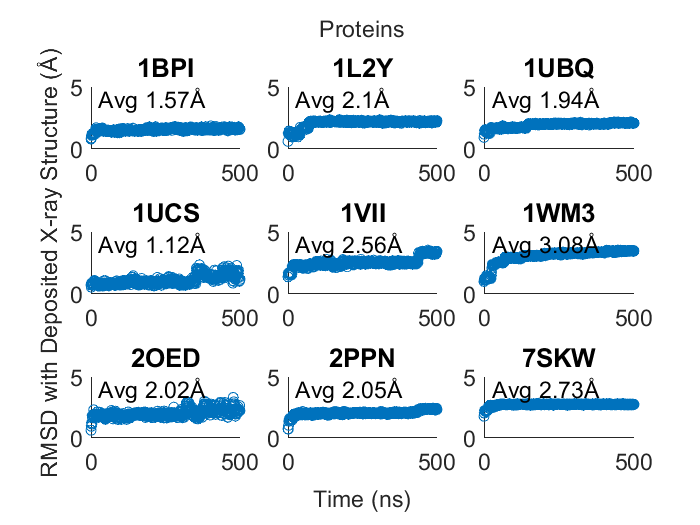

nexttile
plotProts(sampledProteinTable.bbnt_1bpi,fullProteinTable.bbnt_1bpi,'1BPI')
nexttile
plotProts(sampledProteinTable.bbnt_1l2y,fullProteinTable.bbnt_1l2y,'1L2Y')
nexttile
plotProts(sampledProteinTable.bbnt_1ubq,fullProteinTable.bbnt_1ubq,'1UBQ')
nexttile
plotProts(sampledProteinTable.bbnt_1ucs,fullProteinTable.bbnt_1ucs,'1UCS')
nexttile
plotProts(sampledProteinTable.bbnt_1vii,fullProteinTable.bbnt_1vii,'1VII')
nexttile
plotProts(sampledProteinTable.bbnt_1wm3,fullProteinTable.bbnt_1wm3,'1WM3')
nexttile
plotProts(sampledProteinTable.bbnt_2oed,fullProteinTable.bbnt_2oed,'2OED')
nexttile
plotProts(sampledProteinTable.bbnt_2ppn,fullProteinTable.bbnt_2ppn,'2PPN')
nexttile
plotProts(sampledProteinTable.bbnt_7skw,fullProteinTable.bbnt_7skw,'7SKW')
t4.TileSpacing="compact";
title(t4,"Proteins",'FontSize',14)
xlabel(t4,"Time (ns)",'FontSize',14)
ylabel(t4,['RMSD with Deposited X-ray Structure ', '(' Ang ')'],'FontSize',14)

function plotRna(var1, var2, name)
% Plots root mean squared deviation (RMSD) across RNA molecular dynamcics
% trajectories. A sampling of the trajectory is plotted, but all the
% RMSD values in the full trajectory are used in calculating the
% displayed average
    x = linspace(0,500,500);
    scatter(x,var1)
    hold on
    Ang=char(197);
    xlim([0,500])
    ylim([0,5])
    title(name)
    text1 = "Avg " + round(mean(var2),2) + Ang;
    text(25,1,text1,'FontSize',14)
    % Labels for individual plotting
%     xlabel("Time (ns)")
%     ylabel(['RMSD with Deposited Structure ', '(' Ang ')'])
    set(gca,'FontSize',14)
    hold off
end

function plotHairpin(var1, var2, avg1, avg2, name)
% Plots root mean squared deviation (RMSD) across RNA hairpin 
% molecular dynamcics trajectories. A sampling of the trajectory is 
% plotted, but all the RMSD values in the full trajectory are used 
% in calculating the displayed averages. RMSDs are presented for both 
% the full molecule and the stem only, neglecting flexible loop regions
    x=linspace(0,500,500);
    scatter(x,var1)
    hold on
    Ang=char(197);
    scatter(x,var2,'s')
    ylim([0,7])
    xlim([0,500])
    title(name)
    text1 = "All Res: Avg " + round(mean(avg1),2) + Ang;
    text2 = "Stem:    Avg " + round(mean(avg2),2) + Ang;
    legend({text1,text2},'Location',"best",'FontSize',12)
    % Labels for individual plotting
%     xlabel("Time (ns)")
%     ylabel(["RMSD with Deposited NMR Structure","(Angstroms)"])
    set(gca,'FontSize',13)
    hold off
end

function plotDna(var1, var2, name)
% Plots root mean squared deviation (RMSD) across DNA molecular dynamcics
% trajectories. A sampling of the trajectory is plotted, but all the
% RMSD values in the full trajectory are used in calculating the
% displayed average
    x = linspace(0,500,500);
    scatter(x,var1)
    Ang=char(197);
    hold on
    xlim([0,500])
    ylim([0,7])
    title(name)
    text1 = "Avg " + round(mean(var2,"omitnan"),2) + Ang;
    text(300,1.5,text1,'FontSize',14)
    set(gca,'FontSize',14)
    % Labels for individual plotting
%     xlabel("Time (ns)")
%     ylabel(["RMSD with Deposited NMR Structure","(Angstroms)"])
    hold off
end

function plotProts(var1, var2, name)
% Plots root mean squared deviation (RMSD) across protein molecular dynamcics
% trajectories. A sampling of the trajectory is plotted, but all the
% RMSD values in the full trajectory are used in calculating the
% displayed average
    x = linspace(0,500,500);
    scatter(x,var1)
    hold on
    Ang=char(197);
    xlim([0,500])
    ylim([0,5])
    title(name, 'FontSize',10)
    text1 = "Avg " + round(mean(var2),3,'significant') + Ang;
    text(25,4,text1,'FontSize',14)
    % Labels for individual plotting
%     xlabel("Time (ns)")
%     ylabel(['RMSD with Deposited Structure ', '(' Ang ')'])
    set(gca,'FontSize',14)
    hold off
end